#### Macroeconomic Time Series Analysis with Regularisation Methods

This document outlines a complete empirical workflow for analysing a panel of monthly macroeconomic time series, from raw data to modern regularised models. We address seasonality, non-stationarity, missing values, and outliers before studying inflation dynamics, measured by the Consumer Price Index (CPI), using Ridge, Lasso, and factor-based methods.

#### Part 0 - Dataset

FR-M.csv contains a comprehensive set of monthly macroeconomic and financial indicators for France.

Country: France

Frequency: Monthly

Sample period: January 1995 to approximately 2019–2020

Observations: approximately 290 months

Variables: 54 macro-financial

l indicators plus one date column

The dataset spans several dimensions of the French economy, including:

**Real economy and business demography**

The dataset includes indicators related to firm dynamics and real economic activity, such as aggregate and sectoral bankruptcies, construction and housing activity measures, and business conditions indicators.

**Financial and monetary conditions**

This block covers short- and long-term interest rates, term structure indicators and spreads, and monetary and credit aggregates, capturing financial market conditions and monetary policy transmission.

**Labour market conditions**

Labour market information is represented by unemployment rates, reported for the total population and disaggregated by gender.

The CSV file is not provided in a standard tidy format. 

The first row contains descriptive labels for each variable, while numerical observations start from the second row onward. Column headers such as 2, 2.1, or 3.11 are placeholders and must be replaced with meaningful variable names extracted from the first row before performing any analysis.

Dates are reported at monthly frequency using end-of-period dates and should be parsed accordingly.

Typical applications of this dataset include macroeconomic monitoring, business cycle analysis, financial stress and instability measurement, rolling-window econometric analysis, and integration with scale-dependent or network-based indicators.

The workflow that follows uses a **standard large-dataset macro practice** (e.g. FRED):

- Apply economically meaningful transformations

- Accept remaining persistence

- Clean extreme observations

- Normalize

- Model

#### Part. 1 Upload and tidy up data





clear all

data = readmatrix('FR-M.csv');   % numeric part
raw  = readcell('FR-M.csv');    % text + numeric

tcode  = data(1, 2:end);

labels = string(raw(2, 2:end));

dates_str = string(raw(3:end, 1));

dates = datetime(dates_str, 'InputFormat','dd-MMM-yyyy');  % change if needed

X = data(3:end, 2:end);


% truncate ONLY the too-long names
L = namelengthmax;
tooLong = strlength(labels) > L;
labels(tooLong) = extractBefore(labels(tooLong), L+1);


labels = matlab.lang.makeValidName(labels);%enforce MATLAB rules
labels = matlab.lang.makeUniqueStrings(labels);%ensure labels are unique

TT = array2timetable(X, 'RowTimes', dates, 'VariableNames', cellstr(labels));





Does this series systematically behave differently in certain months? 

If yes, that’s seasonality. It’s a calendar effect. But if we leave it there, our model might focus on the calendar instead of the economic relationships. So we automatically test for a monthly pattern and, only when needed, we remove it.

alpha = 0.10;  % set the significance level
dates = TT.Properties.RowTimes;
Y     = TT.Variables;

n = height(TT);
p = width(TT);

m = month(dates);                      % 1..12
D = dummyvar(categorical(m));          % n x 12
Xfull = [ones(n,1), D(:,2:end)];       % intercept + 11 dummies (drop month 1)
Xnull = ones(n,1);                     % intercept-only

Y_sa      = Y;
pvals     = nan(1,p);
changedIx = [];

for j = 1:p
    Z = Y(:,j);
    ok = ~isnan(Z);

    Zok = Z(ok);
    Xf  = Xfull(ok,:);
    X0  = Xnull(ok,:);

    if numel(Zok) <= size(Xf,2)
        continue
    end

    % Fit null and full models
    b0  = X0 \ Zok;
    r0  = Zok - X0*b0;
    SSR0 = sum(r0.^2);

    bf  = Xf \ Zok;
    rf  = Zok - Xf*bf;
    SSR1 = sum(rf.^2);

    df1 = size(Xf,2) - size(X0,2);     % 11
    df2 = numel(Zok) - size(Xf,2);

    F    = ((SSR0 - SSR1)/df1) / (SSR1/df2);
    pval = 1 - fcdf(F, df1, df2);
    pvals(j) = pval;

    if pval <= alpha
        % ----------------------------------------------------------
        % Seasonal adjustment that keeps the mean level:
        % seasonal component = (full fit) - (intercept-only fit)
        % ----------------------------------------------------------
        Zhat_full = Xf * bf;           % mean + seasonal pattern
        Zhat_mean = X0 * b0;           % mean only
        seasonal  = Zhat_full - Zhat_mean;

        Zadj = Z;
        Zadj(ok) = Zok - seasonal;     % remove seasonality, keep mean
        Y_sa(:,j) = Zadj;

        changedIx(end+1) = j;
    end
end

TT_sa = TT;
TT_sa.Variables = Y_sa;

disp("Seasonally adjusted series: " + numel(changedIx) + " out of " + p);

Seasonally adjusted series: 4 out of 54


disp(TT.Properties.VariableNames(changedIx));

    {'ConstructionStatus_Number_Residential_Total_ExcludingMayotte__FrenchMinistryOfEcology_SustainableDevelopment_Energy_SOeS__Permits'}    {'ConstructionStatus_Number_Residential_Total_WholeFrance__FrenchMinistryOfEcology_SustainableDevelopment_Energy_SOeS__Permits'}    {'MetalProduction_CrudeSteel'}    {'Oil_Gas_TotalPetroleumConsumption'}



**Stationarisation via t-codes**

Following the FRED-MD and macroeconometric tradition, each variable is transformed according to a pre-assigned t-code.

These codes map variables into levels, log-levels, differences, or growth rates, aiming to remove stochastic trends and stabilise variance.

This approach respects the economic interpretation of each series and avoids unnecessary over-differencing.

`tcode[j]` tells the program **how economists typically stationarize that variable**.

These codes come from **FRED-MD / macroeconometric tradition**, not from statistics alone.

**Most macro series are:**

- **Trending** (GDP, prices, production)

- **Multiplicative** (growth proportional to size)

Taking logs and them differences removes trend, the mean becomes constant and the variance is stabilised because

**Δ log(X)** ≈ *growth rate*

and growth rates are often stationary.

**Cases where it may fail:**

- Structural breaks

- Time-varying volatility

- Long memory

- Unit roots in growth rates

- Nonlinear dynamics

Stationarity is **not imposed mechanically**.

Each variable is transformed according to standard macroeconomic conventions (levels, differences, growth rates).

These transformations often induce stationarity by removing trends and stabilising variance, but **this is not guaranteed**.

Therefore, stationarity is **checked ex post** using ADF tests.

Unit root tests have **low power**, especially with short and noisy macroeconomic data.

Using a 10% level reduces the risk of falsely concluding that a series is non-stationary.

Zf = TT_sa.Variables;                         % seasonally adjusted data
dates_sa = TT_sa.Properties.RowTimes;
varNames = TT_sa.Properties.VariableNames;

T = size(Zf,1);
P = size(Zf,2);

Zs = nan(T, P);

for j = 1:P

    ztemp = Zf(:,j);          % original series
    zwt   = tcode(j);         % transformation code

    switch zwt

        case 0
            % --------------------------------------------------
            % Level (already stationary)
            % --------------------------------------------------
            zfo = ztemp;

       case 1
    ztemp(ztemp <= 0) = NaN;
    zfo = log(ztemp);

case 2
    ztemp(ztemp <= 0) = NaN;
    zfo = [NaN; diff(log(ztemp))];

             

        case 3
            % --------------------------------------------------
            % Diff(level) – absolute change
            % --------------------------------------------------
            zfo = [NaN; diff(ztemp)];

        case 4
            % --------------------------------------------------
            % Ratio − 1 – percentage change
            % --------------------------------------------------
            zfo = [NaN; ztemp(2:end)./ztemp(1:end-1) - 1];

        otherwise
            error("Unknown transformation code %g for variable %s", ...
                  zwt, varNames{j});
    end

    % Final safety checks 
    zfo(~isfinite(zfo)) = NaN; % replace invalid values (Inf, -Inf) with NaN
    
zfo = real(zfo);
    Zs(:,j) = zfo;
end

% --------------------------------------------------------------
% Remove rows with any missing values
% --------------------------------------------------------------
okRows = all(~isnan(Zs), 2);
Zs = Zs(okRows,:);
dates_s = dates_sa(okRows);

% Convert back to timetable
TT_s = array2timetable(Zs, ...
    'RowTimes', dates_s, ...
    'VariableNames', varNames);


Missing values generated by transformations are removed, while missing values created by outlier correction are linearly interpolated to preserve the underlying dynamics.

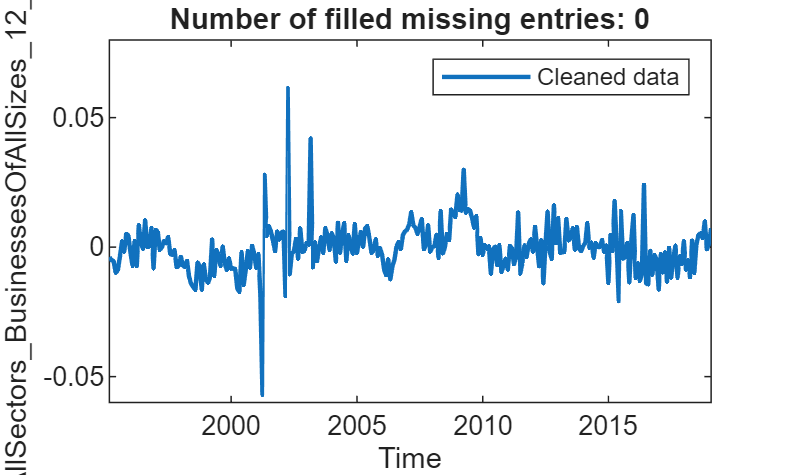

% Fill missing data
[TT_s,missingIndices] = fillmissing(TT_s,"linear");

% Display results
figure

% Plot cleaned data
plot(TT_s.Time,TT_s.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative, ...
    SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(TT_s.Time(missingIndices(:,1)),TT_s.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative(missingIndices(:,1)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,1)))

hold off
legend
ylabel("Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative",Interpreter="none")
xlabel("Time")

clear missingIndices



#### Check for outliers

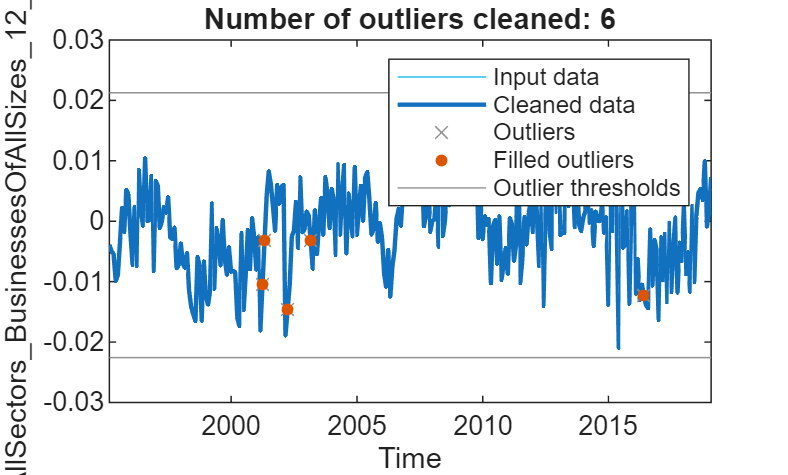

% Fill outliers
[TT_s,outlierIndices,lo,hi] = filloutliers(TT_s,"linear");

% Display results
figure
plot(TT_s.Time,TT_s.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative, ...
    SeriesIndex=6,DisplayName="Input data")
hold on
plot(TT_s.Time,TT_s.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative, ...
    SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")

% Plot outliers
plot(TT_s.Time(outlierIndices(:,1)),TT_s.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative(outlierIndices(:,1)), ...
    "x",Color=[145 145 145]/255,DisplayName="Outliers")

% Plot filled outliers
plot(TT_s.Time(outlierIndices(:,1)),TT_s.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative(outlierIndices(:,1)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim], ...
    [lo.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative lo.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative missing hi.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative hi.Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative], ...
    Color=[145 145 145]/255,DisplayName="Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,1)))
legend
ylabel("Bankruptcies_AllSectors_BusinessesOfAllSizes_12_MonthCumulative",Interpreter="none")
xlabel("Time")

clear lo hi

**Ex-post verification of stationarity**

Although the t-code transformations are designed to induce stationarity based on economic reasoning, stationarity is not guaranteed by construction.

Therefore, after removing missing values created by the transformations and cleaning extreme observations, we formally assess stationarity using Augmented Dickey–Fuller (ADF) tests.


pADF = nan(1, width(TT_s));

for j = 1:width(TT_s)
    z = TT_s{:,j};

    
    [~, pValue] = adftest(z);   
    pADF(j) = pValue;
end

find(pADF > 0.10)  


ans =

  1×0 empty double row vector



#### Part 2. Regularization techniques (Ridge and Lasso)

2.1 Ridge

Target: "Consumer Price Index, Total, Index"


% ----------------------------
% 0) Extract target + predictors
% ----------------------------
Zclean   = TT_s.Variables;
varNames = string(TT_s.Properties.VariableNames);

ixY = find(contains(varNames,"Consumer","IgnoreCase",true) & ...
           contains(varNames,"Price","IgnoreCase",true) & ...
           contains(varNames,"Index","IgnoreCase",true), 1);

if isempty(ixY)
    error("Target CPI not found. Check TT_s.Properties.VariableNames.");
end

disp("Target variable selected:");

Target variable selected:


disp(varNames(ixY));

ConsumerPriceIndex_Total_Index



y = Zclean(:, ixY);
X = Zclean;  X(:, ixY) = [];
xlabels = varNames; xlabels(ixY) = [];

% Keep only finite rows
ok = isfinite(y) & all(isfinite(X), 2);
y = y(ok);
X = X(ok,:);

% Drop near-constant predictors
sdx  = std(X, 0, 1, 'omitnan');
keep = sdx > 1e-10;
X = X(:, keep);
xlabels = xlabels(keep);

% ----------------------------
% 1) Standardise 
% ----------------------------
y = (y - mean(y,'omitnan')) ./ std(y,0,'omitnan');

muX = mean(X, 1, 'omitnan');
sdX = std(X, 0, 1, 'omitnan');
sdX(sdX < 1e-12) = 1;
X = (X - muX) ./ sdX;

% ----------------------------
% 2) CV folds (shared by Ridge & Lasso)
% ----------------------------
K = 10;
rng(1); % reproducible folds
cvp = cvpartition(length(y), 'KFold', K);

%% ============================================================
% RIDGE (L2): manual K-fold CV over lambda
% glmnet-style scaling: (lambda * ntr)
%% ============================================================
lambdaGridR = logspace(-6, 2, 80);
mseR = nan(size(lambdaGridR));

for k = 1:numel(lambdaGridR)
    lam = lambdaGridR(k);
    foldMSE = nan(K,1);

    for f = 1:K
        iTr = training(cvp, f);
        iTe = test(cvp, f);

        Xtr = X(iTr,:); ytr = y(iTr);
        Xte = X(iTe,:); yte = y(iTe);

        % Add intercept (not penalized)
        Xtr1 = [ones(sum(iTr),1), Xtr];
        Xte1 = [ones(sum(iTe),1), Xte];

        p1 = size(Xtr1,2);
        I = eye(p1); I(1,1) = 0;

        ntr = sum(iTr);
        beta = (Xtr1'*Xtr1 + (lam*ntr)*I) \ (Xtr1'*ytr);

        yhat = Xte1 * beta;
        foldMSE(f) = mean((yte - yhat).^2);
    end

    mseR(k) = mean(foldMSE);
end

[~, ixBestR] = min(mseR);
lambda_R = lambdaGridR(ixBestR);
fprintf("\nRIDGE: lambda.min = %.6g\n", lambda_R);


RIDGE: lambda.min = 0.00889953


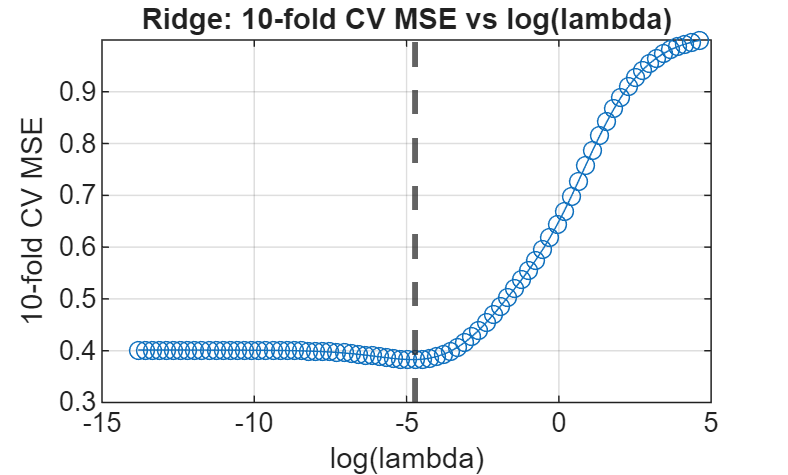


% Fit final ridge on full sample
X1 = [ones(size(X,1),1), X];
p1 = size(X1,2);
I = eye(p1); I(1,1) = 0;
n = size(X,1);
bR = (X1'*X1 + (lambda_R*n)*I) \ (X1'*y);

% --- Ridge CV plot vs log(lambda) (like R)
figure;
plot(log(lambdaGridR), mseR, '-o'); grid on;
xlabel("log(lambda)");
ylabel("10-fold CV MSE");
title("Ridge: 10-fold CV MSE vs log(lambda)");
xline(log(lambda_R), '--', 'LineWidth', 2);


% Save Ridge betas
saveR = table(["Intercept"; xlabels'], bR, abs(bR), ...
    'VariableNames', {'Variable','Beta','AbsBeta'});
writetable(saveR, "Ridge_betas.csv");
disp("Saved: Ridge_betas.csv");

Saved: Ridge_betas.csv



lambdaGridL = logspace(-6, 0, 120);




2.2 LASSO

[B_L, Fit_L] = lasso(X, y, ...
    'Alpha', 1, ...
    'CV', cvp, ...                 % same folds as Ridge
    'Lambda', lambdaGridL, ...
    'Standardize', false, ...
    'Intercept', true, ...
    'RelTol', 1e-6, ...
    'MaxIter', 1e5);

lambda_L = Fit_L.LambdaMinMSE;
lambda_1se = Fit_L.Lambda1SE;
idxMin = Fit_L.IndexMinMSE;
idx1se = Fit_L.Index1SE;

fprintf("\nLASSO: lambda.min = %.6g | lambda.1se = %.6g\n", lambda_L, lambda_1se);


LASSO: lambda.min = 0.0121348 | lambda.1se = 0.0307181


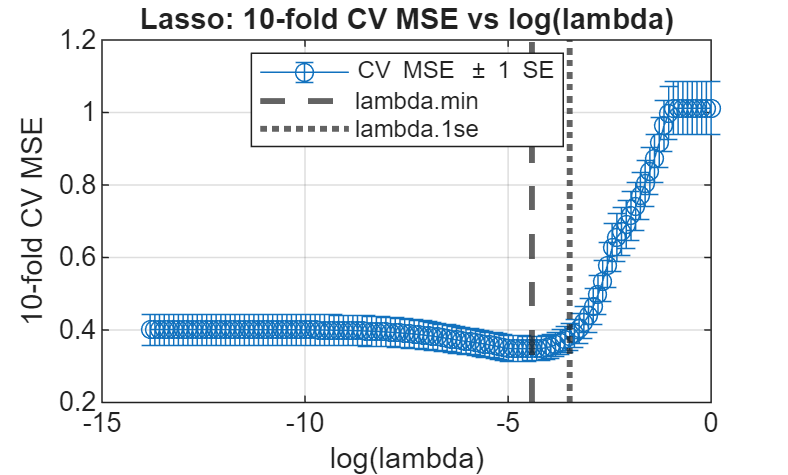


% Coefficients at lambda.min (include intercept)
bL_min = [Fit_L.Intercept(idxMin); B_L(:, idxMin)];
bL_1se = [Fit_L.Intercept(idx1se); B_L(:, idx1se)];

% --- Lasso CV plot vs log(lambda) (like R)
figure;
errorbar(log(Fit_L.Lambda), Fit_L.MSE, Fit_L.SE, 'o-'); grid on;
xlabel("log(lambda)");
ylabel("10-fold CV MSE");
title("Lasso: 10-fold CV MSE vs log(lambda)");
xline(log(lambda_L),  '--', 'LineWidth', 2);
xline(log(lambda_1se),':',  'LineWidth', 2);
legend("CV MSE \pm 1 SE","lambda.min","lambda.1se","Location","best");

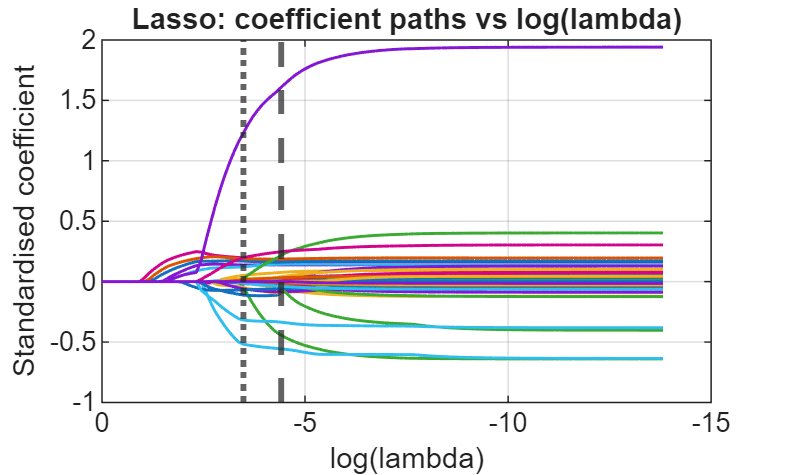


% --- Lasso coefficient paths vs log(lambda) 
% B_L is p x nLambda, plot all coefficient paths
figure;
plot(log(Fit_L.Lambda), B_L', 'LineWidth', 1); grid on;
xlabel("log(lambda)");
ylabel("Standardised coefficient");
title("Lasso: coefficient paths vs log(lambda)");
xline(log(lambda_L),  '--', 'LineWidth', 2);
xline(log(lambda_1se),':',  'LineWidth', 2);

% Optionally reverse x-axis to match glmnet (large lambda on left)
set(gca,'XDir','reverse');


% Save Lasso betas (lambda.min)
saveL = table(["Intercept"; xlabels'], bL_min, abs(bL_min), ...
    'VariableNames', {'Variable','Beta','AbsBeta'});
writetable(saveL, "Lasso_betas.csv");
disp("Saved: Lasso_betas.csv");

Saved: Lasso_betas.csv


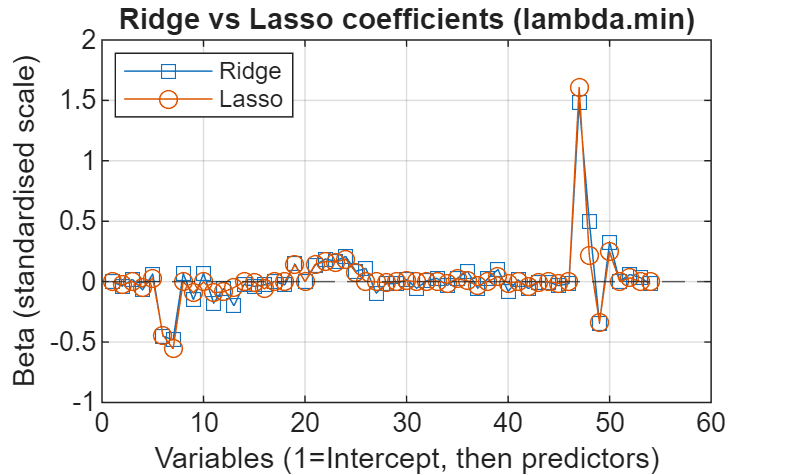


%% ============================================================
% Compare Ridge vs Lasso (lambda.min for each)
%% ============================================================
% Make them same length by using intercept + p predictors
Bcmp = [bR, bL_min];

figure;
plot(Bcmp(:,1), '-s'); hold on;
plot(Bcmp(:,2), '-o');
yline(0, '--');
grid on;
title("Ridge vs Lasso coefficients (lambda.min)");
xlabel("Variables (1=Intercept, then predictors)");
ylabel("Beta (standardised scale)");
legend("Ridge","Lasso","Location","best");
hold off;

At the value of λ that minimises the cross-validated MSE, the Lasso model still includes a relatively large number of regressors.

This is expected, since cross-validation prioritises predictive accuracy rather than sparsity.

For interpretability, we therefore also consider the more conservative choice λ₁ₛₑ, which yields a sparser model with similar predictive performance.

#### Part 3. PCA, PCR and PLS

 Target: Consumer Price Index, Total, Index




% --- Extract data and names
Z = TT_s.Variables;
varNames = string(TT_s.Properties.VariableNames);

% --- Find CPI target (robust match)
yPos = find(contains(varNames,"Consumer","IgnoreCase",true) & ...
            contains(varNames,"Price","IgnoreCase",true) & ...
            contains(varNames,"Index","IgnoreCase",true), 1);

if isempty(yPos)
    error("Target CPI not found. Check TT_s.Properties.VariableNames.");
end

disp("Target variable selected:");

Target variable selected:


disp(varNames(yPos));

ConsumerPriceIndex_Total_Index



% --- Build y and x
y = Z(:, yPos);
x = Z;
x(:, yPos) = [];

xlabels = varNames;
xlabels(yPos) = [];   % keep long labels for later

% --- Remove non-finite rows (safety)
ok = isfinite(y) & all(isfinite(x),2);
y  = y(ok);
x  = x(ok,:);

n = size(x,1);
p = size(x,2);

% --- Remove (near) constant predictors (helps rank issues)
sdx  = std(x, 0, 2); % (row std not used)
sdx  = std(x, 0, 1, 'omitnan');    % column std
keep = sdx > 1e-10;                % tolerance 

x = x(:, keep);
xlabels = xlabels(keep);

n = size(x,1);
p = size(x,2);

% --- Rank + maximum feasible components
r = rank(x);
maxComp = min(r, p);

fprintf("Predictors after filtering: p = %d\n", p);

Predictors after filtering: p = 53


fprintf("Rank(X) = %d (rank-deficient if rank < p)\n", r);

Rank(X) = 51 (rank-deficient if rank < p)



% Optional short names like in R: x1, x2, ...
xShortNames = "x" + string(1:p);


3.1 PCA with k=3


k = min(3, maxComp);

% PCA on X (already standardized, so no extra scaling)
% Use SVD algorithm + limit components to avoid warnings about TSQUARED
[coeff, score, latent, ~, explained] = pca(x, ...
    'Algorithm', 'svd', ...
    'NumComponents', maxComp);


% Explained variance for first k components
explained_k = explained(1:k);
disp("PCA explained variance (%) for first k components:");

PCA explained variance (%) for first k components:


disp(explained_k);

   45.6455
   20.2963
   11.5012



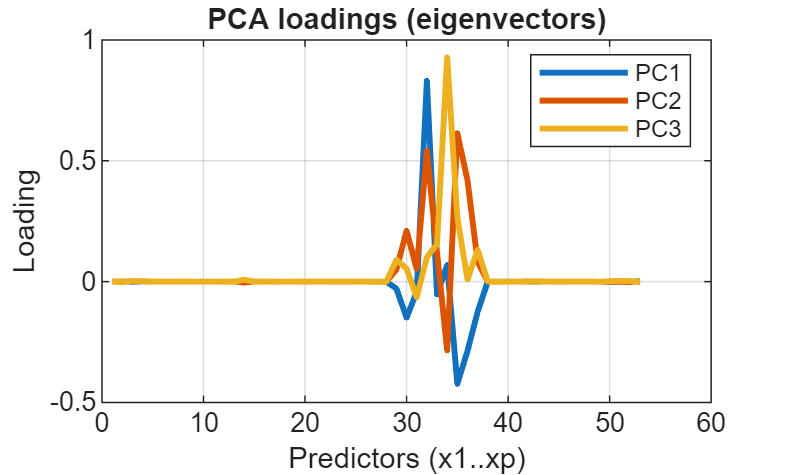


% Plot loadings (each curve is one eigenvector = loadings)
figure;
plot(coeff(:,1:k), 'LineWidth', 2);
grid on;
title("PCA loadings (eigenvectors)");
xlabel("Predictors (x1..xp)");
ylabel("Loading");
legend("PC1","PC2","PC3","Location","best");

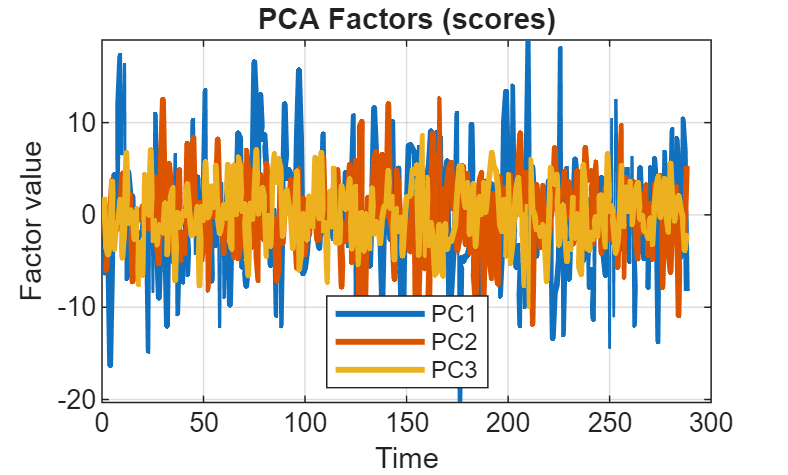


% Plot first k factors (scores)
v = score(:,1:k);
vlims = [min(v(:)) max(v(:))];

figure;
plot(v(:,1), 'LineWidth', 2); hold on;
if k >= 2, plot(v(:,2), 'LineWidth', 2); end
if k >= 3, plot(v(:,3), 'LineWidth', 2); end
ylim(vlims);
grid on;
title("PCA Factors (scores)");
xlabel("Time");
ylabel("Factor value");
legend("PC1","PC2","PC3","Location","best");
hold off;

3.2 PCA choosing the number of components


K = 10;
cvp = cvpartition(n, 'KFold', K);

msePCR = nan(maxComp, 1);

for a = 1:maxComp
    foldMSE = nan(K,1);

    for f = 1:K
        iTr = training(cvp, f);
        iTe = test(cvp, f);

        Xtr = x(iTr,:);
        ytr = y(iTr);
        Xte = x(iTe,:);
        yte = y(iTe);

      
        % Limit to 'a' components, use SVD for stability
        [C, S_tr] = pca(Xtr, 'Algorithm','svd', 'NumComponents', a);

        % Regression of y on factor scores (PCR)
        beta = [ones(size(S_tr,1),1), S_tr] \ ytr;

        % Project test set onto training PCs:
     
        XtrMean = mean(Xtr, 1);
        S_te = (Xte - XtrMean) * C;

        yhat = [ones(size(S_te,1),1), S_te] * beta;
        foldMSE(f) = mean((yte - yhat).^2);
    end

    msePCR(a) = mean(foldMSE);
end

[~, mseoptPCR] = min(msePCR);
fprintf("\nPCR: #components (min CV MSE) = %d\n", mseoptPCR);


PCR: #components (min CV MSE) = 50


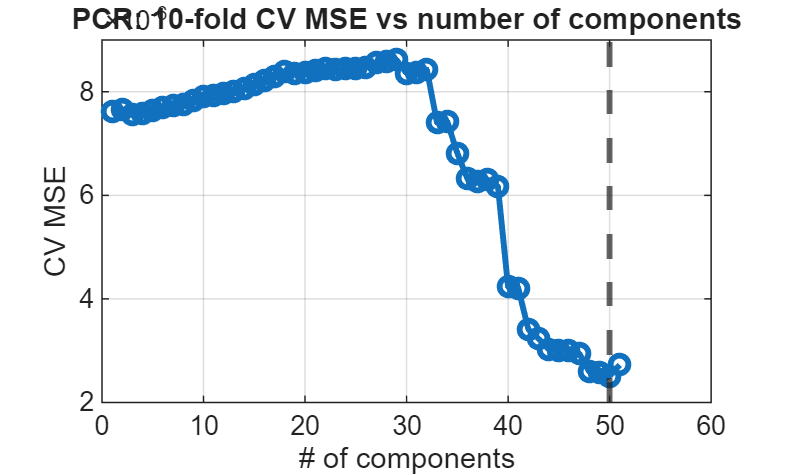


figure;
plot(1:maxComp, msePCR, '-o', 'LineWidth', 2);
grid on;
title("PCR: 10-fold CV MSE vs number of components");
xlabel("# of components");
ylabel("CV MSE");
xline(mseoptPCR, '--', 'LineWidth', 2);


% Explained variance thresholds (80/90/95) using PCA on full X
[~, ~, ~, ~, explainedAll] = pca(x, 'Algorithm','svd', 'NumComponents', maxComp);

vsc = cumsum(explainedAll);

kf1 = find(vsc <= 80, 1, 'last');
kf2 = find(vsc <= 90, 1, 'last');
kf3 = find(vsc <= 95, 1, 'last');

% Handle edge cases (if first component already exceeds threshold)
if isempty(kf1), kf1 = 1; end
if isempty(kf2), kf2 = 1; end
if isempty(kf3), kf3 = 1; end

fprintf("PCR: components for <=80%%, <=90%%, <=95%% variance: %d, %d, %d\n", kf1, kf2, kf3);

PCR: components for <=80%, <=90%, <=95% variance: 3, 4, 5


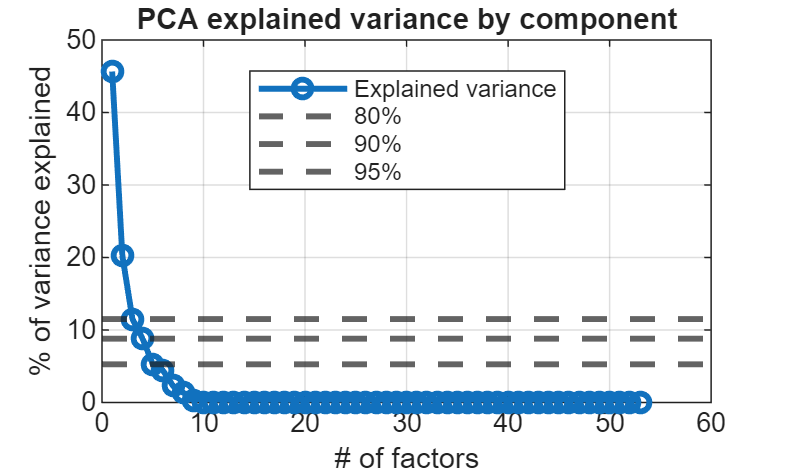


figure;
plot(explainedAll, '-o', 'LineWidth', 2);
grid on;
title("PCA explained variance by component");
xlabel("# of factors");
ylabel("% of variance explained");
yline(explainedAll(kf1), '--', 'LineWidth', 2);
yline(explainedAll(kf2), '--', 'LineWidth', 2);
yline(explainedAll(kf3), '--', 'LineWidth', 2);
legend("Explained variance", "80%", "90%", "95%", "Location", "best");

3.3 PLS with 10 fold CV


msePLS = nan(maxComp, 1);

for a = 1:maxComp
    foldMSE = nan(K,1);

    for f = 1:K
        iTr = training(cvp, f);
        iTe = test(cvp, f);

        Xtr = x(iTr,:);
        ytr = y(iTr);
        Xte = x(iTe,:);
        yte = y(iTe);

        % plsregress returns regression coefficients for 'a' components
        % betaPLS includes intercept as first element
        [~,~,~,~,betaPLS] = plsregress(Xtr, ytr, a);

        yhat = [ones(size(Xte,1),1), Xte] * betaPLS;
        foldMSE(f) = mean((yte - yhat).^2);
    end

    msePLS(a) = mean(foldMSE);
end

[~, mseoptPLS] = min(msePLS);
fprintf("\nPLS: #components (min CV MSE) = %d\n", mseoptPLS);


PLS: #components (min CV MSE) = 40


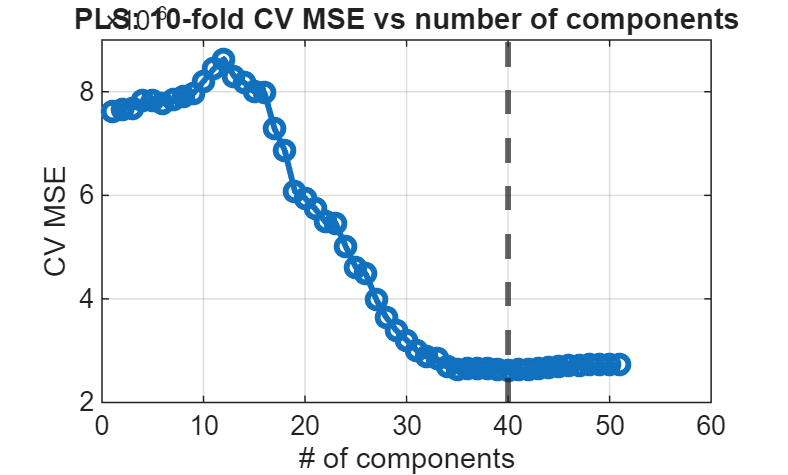


figure;
plot(1:maxComp, msePLS, '-o', 'LineWidth', 2);
grid on;
title("PLS: 10-fold CV MSE vs number of components");
xlabel("# of components");
ylabel("CV MSE");
xline(mseoptPLS, '--', 'LineWidth', 2);


% Explained variance in X for PLS
% pctVar(1,:) = fraction of X variance explained by each component
[~,~,~,~,~,pctVar] = plsregress(x, y, maxComp);
vsPLS  = 100 * pctVar(1,:);           % % variance in X explained by each comp
vscPLS = cumsum(vsPLS);

kf1p = find(vscPLS <= 80, 1, 'last');
kf2p = find(vscPLS <= 90, 1, 'last');
kf3p = find(vscPLS <= 95, 1, 'last');

if isempty(kf1p), kf1p = 1; end
if isempty(kf2p), kf2p = 1; end
if isempty(kf3p), kf3p = 1; end

fprintf("PLS: components for <=80%%, <=90%%, <=95%% X-variance: %d, %d, %d\n", kf1p, kf2p, kf3p);

PLS: components for <=80%, <=90%, <=95% X-variance: 3, 5, 7


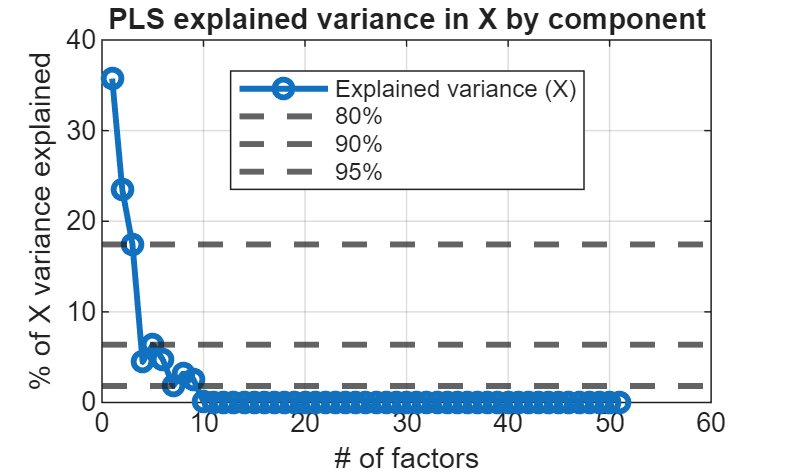


figure;
plot(vsPLS, '-o', 'LineWidth', 2);
grid on;
title("PLS explained variance in X by component");
xlabel("# of factors");
ylabel("% of X variance explained");
yline(vsPLS(kf1p), '--', 'LineWidth', 2);
yline(vsPLS(kf2p), '--', 'LineWidth', 2);
yline(vsPLS(kf3p), '--', 'LineWidth', 2);
legend("Explained variance (X)", "80%", "90%", "95%", "Location", "best");